close all;
clear;
clc;
load data/threeTankParameter1.mat
%load data/testData1.mat
load dataOut/testData5.mat
addpath(genpath('lib'),genpath('gpml-matlab-master'));

xD = [testData.x1,testData.x2,testData.x3];
dxD = [testData.dx1,testData.dx2,testData.dx3];
yD = [testData.y1,testData.y2,testData.y3];
uD = testData.u1;
n = 3;
m = 3;

u1Full = uD(1);
u1Half = u1Full * 0.5;
u1TQ = uD(1)* 0.75

u1TQ = 7.5960e-05


parameter.u1 = u1Full;


% hyperparameterR1 = calcHyperparameter([xD(:,1)-xD(:,3),uD],dxD(:,1));
% hyperparameterR2 = calcHyperparameter([xD(:,3)-xD(:,2),xD(:,2)],dxD(:,2));
% hyperparameterR3 = calcHyperparameter([xD(:,1)-xD(:,3),xD(:,3)-xD(:,2)],dxD(:,3));

hyperparameterR1 = calcHyperparameter([xD,uD],dxD(:,1));

Function evaluation      0;  Value 2.472591e+01
Function evaluation     10;  Value -2.633441e+02
Function evaluation     15;  Value -2.729499e+02
Function evaluation     17;  Value -2.738900e+02
Function evaluation     18;  Value -2.750776e+02
Function evaluation     20;  Value -2.753701e+02
Function evaluation     22;  Value -2.763354e+02
Function evaluation     24;  Value -2.770328e+02
Function evaluation     27;  Value -2.770520e+02
Function evaluation     29;  Value -2.770520e+02
Function evaluation     31;  Value -2.770521e+02
Function evaluation     33;  Value -2.770521e+02
Function evaluation     35;  Value -2.770521e+02
Function evaluation     38;  Value -2.770521e+02
Function evaluation     40;  Value -2.770521e+02
Function evaluation     42;  Value -2.770521e+02
Function evaluation     44;  Value -2.770521e+02
Function evaluation     46;  Value -2.770521e+02
Function evaluation     48;  Value -2.770521e+02
Function evaluation     50;  Value -2.770521e+02
Function evaluation  

hyperparameterR2 = calcHyperparameter([xD,uD],dxD(:,2));

Function evaluation      0;  Value 4.116952e+01
Function evaluation      8;  Value -7.189629e+01
Function evaluation     11;  Value -1.570422e+02
Function evaluation     17;  Value -1.712202e+02
Function evaluation     20;  Value -1.714452e+02
Function evaluation     22;  Value -1.715681e+02
Function evaluation     25;  Value -1.715756e+02
Function evaluation     27;  Value -1.715816e+02
Function evaluation     29;  Value -1.715823e+02
Function evaluation     31;  Value -1.715829e+02
Function evaluation     34;  Value -1.715830e+02
Function evaluation     36;  Value -1.715830e+02
Function evaluation     38;  Value -1.715830e+02
Function evaluation     40;  Value -1.715830e+02
Function evaluation     42;  Value -1.715830e+02
Function evaluation     44;  Value -1.715830e+02
Function evaluation     46;  Value -1.715830e+02
Function evaluation     48;  Value -1.715830e+02
Function evaluation     50;  Value -1.715830e+02
Function evaluation     52;  Value -1.715830e+02
Function evaluation  

hyperparameterR3 = calcHyperparameter([xD,uD],dxD(:,3));

Function evaluation      0;  Value 2.362662e+01
Function evaluation     14;  Value -3.367529e+02
Function evaluation     19;  Value -3.473957e+02
Function evaluation     21;  Value -3.537543e+02
Function evaluation     22;  Value -3.605255e+02
Function evaluation     25;  Value -3.609395e+02
Function evaluation     27;  Value -3.610706e+02
Function evaluation     30;  Value -3.610707e+02
Function evaluation     32;  Value -3.610709e+02
Function evaluation     34;  Value -3.610710e+02
Function evaluation     37;  Value -3.610714e+02
Function evaluation     40;  Value -3.610714e+02
Function evaluation     42;  Value -3.610714e+02
Function evaluation     45;  Value -3.610714e+02
Function evaluation     48;  Value -3.610714e+02
Function evaluation     50;  Value -3.610714e+02
Function evaluation     52;  Value -3.610714e+02
Function evaluation     54;  Value -3.610714e+02
Function evaluation     63;  Value -3.610714e+02


%%own hyper variation 
hyperparameter.sigmaN = 0.56;
hyperparameter.sigmaF = 0.86;
hyperparameter.l = 0.43;

%%GPML
hyperparameter.sigmaN = 0.5096; 
hyperparameter.sigmaF = 0.9494;
hyperparameter.l  = 0.3483;

%%GPML
hyperparameter.sigmaN = 0.5; 
hyperparameter.sigmaF = 0.9;
hyperparameter.l  = 0.35;

%%with u
hyperparameterDx1.l = 4.7944;
hyperparameterDx1.sigmaF  = 2.5453;
hyperparameterDx1.sigmaN  = 0.1972;

hyperparameterDx2.l = 2.0278;
hyperparameterDx2.sigmaF = 0.5450;
hyperparameterDx2.sigmaN = 0.8670;

hyperparameterDx3.l = 9.1640;
hyperparameterDx3.sigmaF =  4.3155;
hyperparameterDx3.sigmaN =  0.3822;

hyperparameterY.l = 7.4747;
hyperparameterY.sigmaF =  0.7853;
hyperparameterY.sigmaN = 8.9081e-08;


hyperparameterDel1.l = 5.4710;
hyperparameterDel1.sigmaF =  3.4551;
hyperparameterDel1.sigmaN =  0.1983;

hyperparameterDel2.l = 6.4719;
hyperparameterDel2.sigmaF = 5.1257;
hyperparameterDel2.sigmaN = 0.8485;

hyperparameterDel3.l = 0.8365;
hyperparameterDel3.sigmaF = 0.4727;
hyperparameterDel3.sigmaN = 0.9218;


sigmaX = [1e-7, 0, 0; 0, 1e-7, 0; 0, 0, 1e-7];
sigmaY = [5e-6, 0, 0; 0, 5e-6, 0; 0, 0, 5e-6];
kernelTank= {@seKernelThreeTank1,@seKernelThreeTank2,@seKernelThreeTank3};
kernelSE = {@squaredExponentialKernel, @squaredExponentialKernel, @squaredExponentialKernel};
meanFctTank = {@meanDx1,@meanDx2,@meanDx3};
meanFctZero = {@zeroMean,@zeroMean,@zeroMean};

hyperparameter1 = hyperparameter;
hyperparameter2 = hyperparameter;
hyperparameter3 =  hyperparameter;
 hyperparameter1.beta = [1; 2.4e-05*0.5];
 hyperparameter2.beta = [2e-05; 3e-05];
 hyperparameter3.beta = [2.4e-05; 2.4e-05].*0.5;
 hyperparameter1.B = [ 1e-07^2 , 0 ; 0 , 1e-04^2];
 hyperparameter2.B = [ 1e-04^2 , 0 ; 0 , 1e-04^2];
 hyperparameter3.B = [ 1e-04^2 , 0 ; 0 , 1e-04^2];
% 
%  hyperparameter1.beta = [0; 0];
%  hyperparameter2.beta = [0; 0];
%  hyperparameter3.beta = [0; 0];

hyperparameterCell = {hyperparameter1, hyperparameter2, hyperparameter3};
hyperTrans = {hyperparameterDx1, hyperparameterDx2, hyperparameterDx3};
hyperDel = {hyperparameterDel1,hyperparameterDel2,hyperparameterDel3};
hyperR = {hyperparameterR1,hyperparameterR2,hyperparameterR3};


threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);

gP = DynamicSystemGP2(xD,uD,dxD,hyperparameterCell,kernelSE,meanFctTank,sigmaX,sigmaY);

xGP = [0,0,0];
xGpEst = zeros(200,3);
dxGpEst = zeros(200,3);
sigma = zeros(200,3);
yGpEst = zeros(200,3);
x = zeros(200,3);
time = zeros(200,1);
xK = [0,0,0];
SigmaEst = sigmaX;

UKF = UnscentedKalmanFilter2(gP)

UKF =   UnscentedKalmanFilter2 with properties:

           s: 7
           n: 3
           m: 3
       gamma: 1.7321
    weightsM: [7×1 double]
    weightsC: [7×1 double]
      system: [1×1 DynamicSystemGP2]


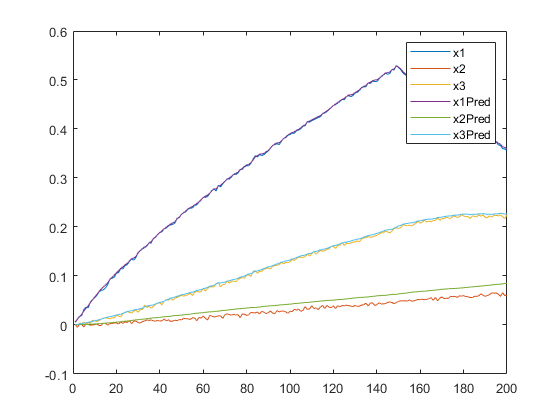

for i = 1 : 150
    time(i) = i;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    tic
    [xGpEst(i,:),SigmaEst] = UKF.prediction(xGP,SigmaEst,yK,parameter.u1,1);
    calcTime(i) = toc;
    
    xGP = xGpEst(i,:);
end
parameter.u1 = 0;
threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);
for i = 150 : 200
     time(i) = i;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    tic
    [xGpEst(i,:),SigmaEst] = UKF.prediction(xGP,SigmaEst,yK,parameter.u1,1);
    calcTime(i) = toc;
    
    xGP = xGpEst(i,:);
end
plot(x)
hold on;
plot(xGpEst(:,1))
plot(xGpEst(:,2))
plot(xGpEst(:,3))
%plot (xD(:,1));
% plot (xD(1:180,2));
legend("x1","x2","x3","x1Pred","x2Pred","x3Pred")
hold off;

mean(calcTime)

ans = 0.0169


%after GP paramater estimation:
beta1 = [-8.48829750901274e-06 ;-3.70816669639603e-06];
beta2 = [7.91168352331322e-06; 1.30833658437821e-05];
beta3 = [1.43846330478310e-07;-8.06572651929482e-07];

!PF is not working any more. could work with some redo


% xGP = [0,0,0];
% xGpEst = zeros(180,3);
% dxGpEst = zeros(180,3);
% sigma = zeros(180,3);
% yGpEst = zeros(180,3);
% x = zeros(180,3);
% time = zeros(180,1);
% xK = [0,0,0];
% pf = ParticleFilter(gP,10);
% for i = 1 : 180
%     %waterTank
%     time(i) = i;
%     xK = threeTank.stateTransition(xK,1);
%     yK = threeTank.measurement(xK);
%     x(i,:) = yK;
%     
%     %GP System
%     tic
%     xGpEst(i,:) = pf.prediction(yK,1);
%     calcTime(i) = toc;
%     
%     [xGP,dxGpEst(i,:),sigma] = gP.stateTransition(xGP,1);
%     sigma(i,:) = diag(sigma).';
%     
%     %xGpEst(i,:) = xGP;
%     %yGpEst(i,:) = gP.measurement(xGP);
% end
% plot(xGpEst);
% hold on;
% plot(x)
% %plot(yGpEst)
% hold off;
% plot(dxGpEst)
% 
% plot(calcTime)
% calcTimeM = mean(calcTime);
% 

% f1 = [dxGpEst(:,1)+2*sqrt(sigma(:,1)); flip(dxGpEst(:,1)-2*sqrt(sigma(:,1)),1)];
% f2 = [dxGpEst(:,2)+2*sqrt(sigma(:,2)); flip(dxGpEst(:,2)-2*sqrt(sigma(:,2)),1)];
% f3 = [dxGpEst(:,3)+2*sqrt(sigma(:,3)); flip(dxGpEst(:,3)-2*sqrt(sigma(:,3)),1)];
% 
% 
% fill([time; flip(time,1)], f1, [7 7 7]/8)
% hold on;
% fill([time; flip(time,1)], f2, [7 7 7]/8)
% fill([time; flip(time,1)], f3, [7 7 7]/8)
% plot(time, dxGpEst(:,1));
% plot(time, dxGpEst(:,2));
% plot(time, dxGpEst(:,3));
% 
% 
% legend('Varianz dx1','Varianz dx2','Varianz dx3', 'dx1 geschätzt', 'dx2 geschätzt', 'dx3 geschätzt');
% xlabel('Zeit t /s')
% ylabel('Fuellstand /m')
% hold off;

function hyperparameter = calcHyperparameter(xD,yD)

n = size(xD,2);
m = size(yD,2);

for i = 1 : n
    xStd(1,i) = std(xD(:,i));
    xMean(1,i) = mean(xD(:,i));

end
for i = 1 : m
    yStd(1,i) = std(yD(:,i));
    yMean(1,i) = mean(yD(:,i));
end

xDnorm = (xD - xMean)./ xStd;
yDnorm = (yD - yMean)./ yStd;

meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;              % Gaussian likelihood
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xDnorm, yDnorm);

hyperparameter.l = exp(hyp2.cov(1)); %length scale
hyperparameter.sigmaF = exp(hyp2.cov(2)); %signal std Dev sigmaF
hyperparameter.sigmaN = exp(hyp2.lik(1)); %noise std dev sigmaN
end